%% Projeto Computacional
% Primeira estrutura de discretização

clear
clc
close all


# 1. Parâmetros físicos

Lx = 1;             % largura [m]
Ly = 1;             % comprimento [m]
Lz = 1;             % altura [m]
rho = 917;          % densidade do gelo [kg/m3]
k = 2.22;           % condutividade térmica do gelo [W/(m⋅K)]
l = 334000;         % Calor latente [J/kg]
h = 15;             % Coeficiente de convecçao de 15-25 [W/(m^2⋅K)]
delta_T = 273.15;    % intervalo numérico de transição de fase [K]

delta_T = 273.1500

# 2.Domínio computacional

Nx = 10;            % numero de pontos no eixo x
Ny = 10;            % numero de pontos no eixo y
Nz = 10;            % numero de pontos no eixo z
delta_x = 0.5;      % intervalo entre pontos em x
delta_y = 0.5;      % intervalo entre pontos em y
delta_z = 0.5;      % intervalo entre pontos em z
delta_t = 0.5;      % intervalo temporal
t0 = 0;             % instante inicial
tf = 15;            % instante final
t = t0:delta_t:tf;  % vetor de pontos no dominio do tempo

# 3.Geração da malha

Inicialmente: Malha uniforme

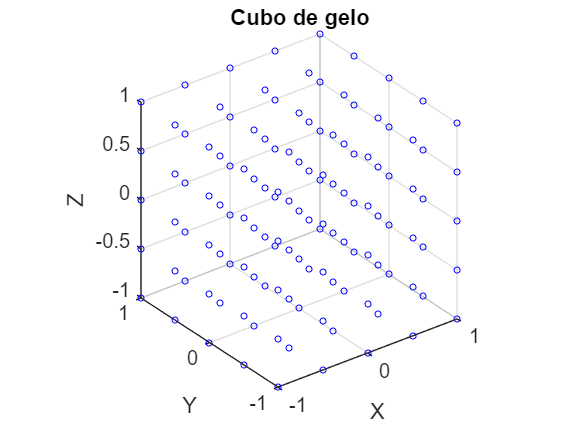

x = -Lx:delta_x:Lx;             %Vetor do eixo x
y = -Ly:delta_y:Ly;             %Vetor do eixo y
z = -Lz:delta_z:Lz;             %Vetor do eixo z
[X,Y,Z] = ndgrid(x,y,z);        %Grelha 3D

%Visualizaçao da grelha
figure;
plot3(X(:), Y(:), Z(:), 'bo', 'MarkerSize', 3);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Cubo de gelo');
axis equal;

# 4.Variáveis e incógnitas

Incognitas: T (em cada ponto da malha tri-dimensional)

Variáveis: X, Y, Z, t

# 5.Equações discretizadas

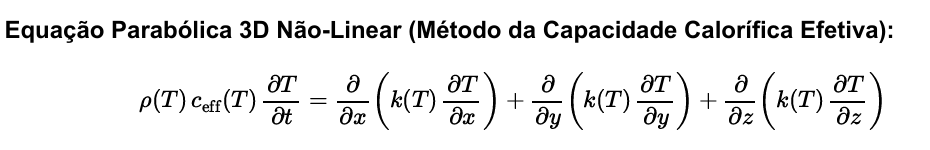

# 6.Condições de fronteira

Condições iniciais: T(x, y, z, 0) = T0 ≤ 0 ∘C (ex.: T0 = −10 ∘C ou − 5 ∘C)

Condições fronteira:

Opção 1 (Dirichlet): Temperatura de ar exterior/aquecimento fixa positiva: 

Opção 2 (Robin): Convecção de calor com o ambiente quente: −k(T) ∂T ∂n = h (T − Tamb)

# 7.Resoluçao Numérica

# 8.Verificação

%TODO

Desenhar malha cubica

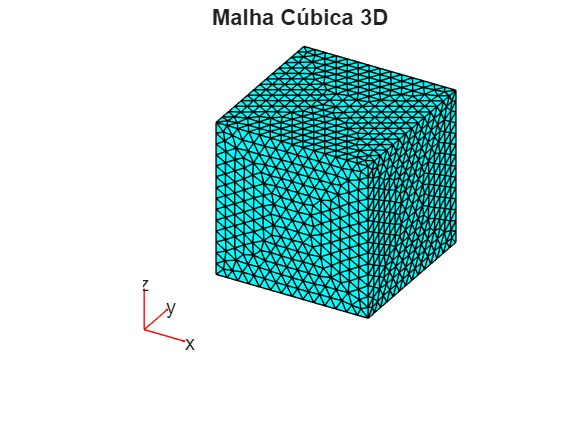

model = createpde();

% Criar geometria de um cubo (multicuboid com dimensões 1x1x1, por exemplo)
geo = multicuboid(1, 1, 1); 
model.Geometry = geo;

% Gerar a malha do cubo (tetraédrica/linear ou quadrática)
mesh = generateMesh(model, 'GeometricOrder', 'linear');

% Visualizar a malha do cubo
pdemesh(model);
title('Malha Cúbica 3D');